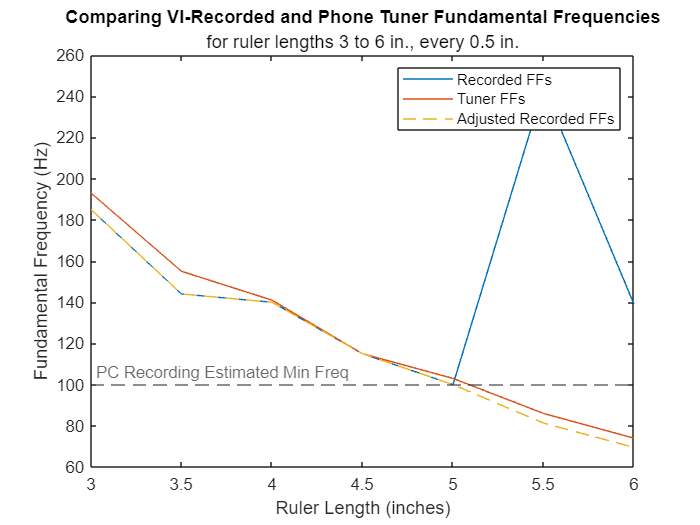

% me45 - finding relationship between ruler length and frequency

lengths = 3:0.5:6;
recorded_ffs = [185 144 140 115 100 244 139];
tuner_ffs = [193 155 141 115 103 86 74];
adj_recorded_ffs = recorded_ffs;
adj_recorded_ffs(end) = adj_recorded_ffs(end)/2; % 6in. is 1 octave too high
adj_recorded_ffs(end-1) = adj_recorded_ffs(end-1)/3; % 5.5in. is 2 octaves too high

figure;
plot(lengths,recorded_ffs)
hold on
plot(lengths,tuner_ffs)
plot(lengths,adj_recorded_ffs, '--')
yl = yline(100,'--','PC Recording Estimated Min Freq');
yl.LabelHorizontalAlignment = 'left';
legend('Recorded FFs','Tuner FFs','Adjusted Recorded FFs')
title('Comparing VI-Recorded and Phone Tuner Fundamental Frequencies')
subtitle('for ruler lengths 3 to 6 in., every 0.5 in.')
xlabel('Ruler Length (inches)')
ylabel('Fundamental Frequency (Hz)')

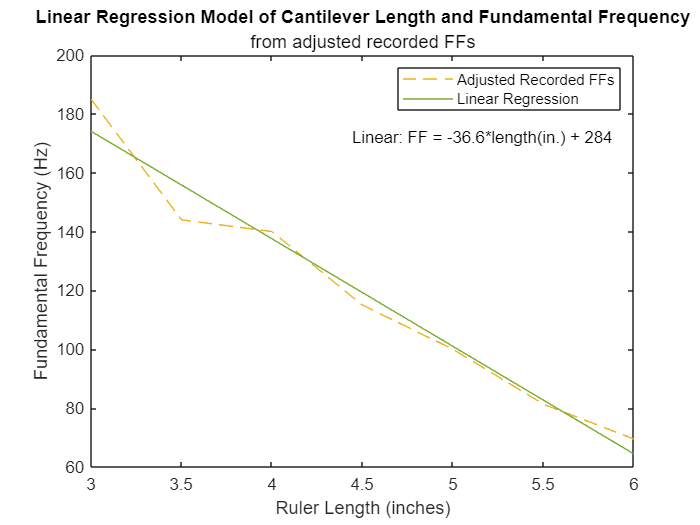


% create normalize/shifted expression to fit exp function
% rising exponential: y=A(1-exp(B*t))+C --> log(-(y-C)/A+1)=B*t, C=Tinit
FF = adj_recorded_ffs;

% setup linear regression
XXDATA = [lengths',ones(length(lengths),1)]; % get time data for trimmed indices
YYDATA = FF'; % get normalize temp data for REAL values (iix) below cutoff time (iiz)
[B,BINT,R,RINT,STATS] = regress(YYDATA,XXDATA); % do linear regression on data

% get new data pts from linear regression
Xmod = lengths; % get time data for real, trimmed indices // ?? what is diff from data.t(iiz) ??
slope = B(1); % extract from regression
offset = B(2); % extract from regression
Ymod = (slope*Xmod) + offset; % calculate temps based on linear reg

% plot the regression over normalized data (get mostly linear data b/c took
% log of log-like data
figure;
plot(lengths,adj_recorded_ffs, '--','Color',"#EDB120") % make gold to match above
hold on
plot(Xmod,Ymod,'Color',"#77AC30") % plot linear regression
legend('Adjusted Recorded FFs','Linear Regression')
title('Linear Regression Model of Cantilever Length and Fundamental Frequency')
subtitle('from adjusted recorded FFs')
xlabel('Ruler Length (inches)')
ylabel('Fundamental Frequency (Hz)')

% show the linear regression equation
eq = strcat("Linear: FF = ",num2str(round(slope,1)),"*length(in.) + ",num2str(round(offset)));
xl = xlim;
yl = ylim;
x_label = ((xl(2)-xl(1)) * 0.48) + xl(1);
y_label = ((yl(2)-yl(1)) * 0.8) + yl(1);
text(x_label,y_label,eq)



% now compare the modal fundamental frequencies
lengths_modal = [4 4.5 5 6];
modal_ffs = [179 141 114 78.7];

% find linear reg of modal ffs
% create normalize/shifted expression to fit exp function
% rising exponential: y=A(1-exp(B*t))+C --> log(-(y-C)/A+1)=B*t, C=Tinit

% setup linear regression
XXDATA = [lengths_modal',ones(length(lengths_modal),1)]; % get time data for trimmed indices
YYDATA = modal_ffs'; % get normalize temp data for REAL values (iix) below cutoff time (iiz)
[B,BINT,R,RINT,STATS] = regress(YYDATA,XXDATA); % do linear regression on data

% get new data pts from linear regression
Xmod_modal = lengths; % get time data for real, trimmed indices // ?? what is diff from data.t(iiz) ??
slope_modal = B(1); % extract from regression
offset_modal = B(2); % extract from regression
Ymod_modal = (slope_modal*Xmod_modal) + offset_modal; % calculate temps based on linear reg

% write analytic expression
l=lengths.*.0254 % need to convert from in to m b/c actually plugging in in terms of m here

l =     0.0762    0.0889    0.1016    0.1143    0.1270    0.1397    0.1524


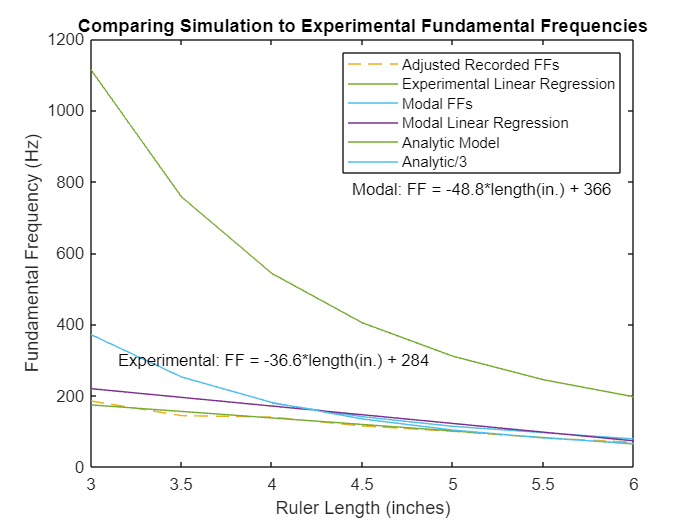

l=l'; % need to transpose for some reason
analytic = 1.7848.*(l.^(-2.5));

figure;
plot(lengths,adj_recorded_ffs, '--','Color',"#EDB120") % make gold to match above
hold on
plot(Xmod,Ymod,'Color',"#77AC30") % plot experimental linear regression
plot(lengths_modal,modal_ffs,'Color',"#4DBEEE") % plot pts for modal ff's
plot(Xmod_modal,Ymod_modal) % plot modal lin reg
plot(lengths,analytic)
plot(lengths,analytic./3)
legend('Adjusted Recorded FFs','Experimental Linear Regression','Modal FFs','Modal Linear Regression', 'Analytic Model','Analytic/3')
title('Comparing Simulation to Experimental Fundamental Frequencies')
xlabel('Ruler Length (inches)')
ylabel('Fundamental Frequency (Hz)')

% show the EXPERIMENTAL linear regression equation
eq = strcat("Experimental: FF = ",num2str(round(slope,1)),"*length(in.) + ",num2str(round(offset)));
xl = xlim;
yl = ylim;
x_label = ((xl(2)-xl(1)) * 0.05) + xl(1);
y_label = ((yl(2)-yl(1)) * 0.25) + yl(1);
text(x_label,y_label,eq)
% show the MODAL linear regression equation
eq = strcat("Modal: FF = ",num2str(round(slope_modal,1)),"*length(in.) + ",num2str(round(offset_modal)));
xl = xlim;
yl = ylim;
x_label = ((xl(2)-xl(1)) * 0.48) + xl(1);
y_label = ((yl(2)-yl(1)) * 0.65) + yl(1);
text(x_label,y_label,eq)